## MMSE function:

### Uniform Prior Knowledge:

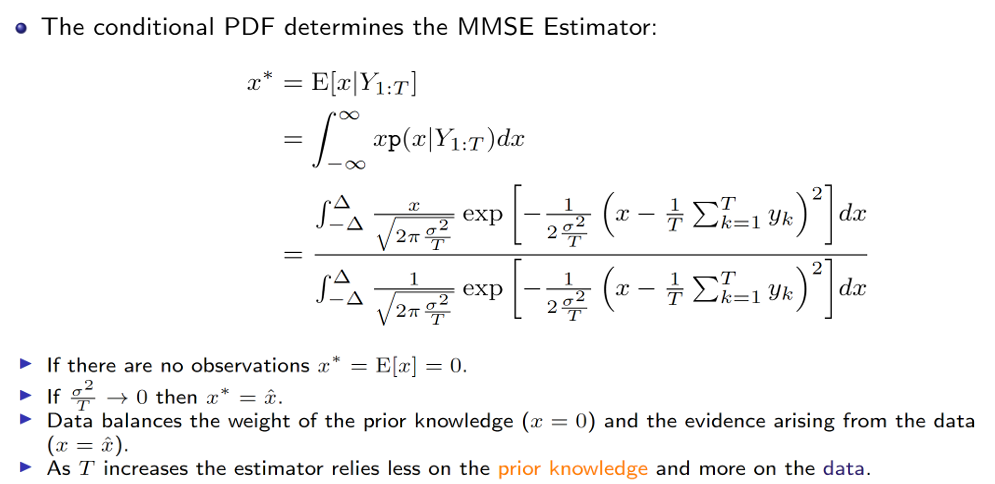

### Gaussian Prior Knowledge:

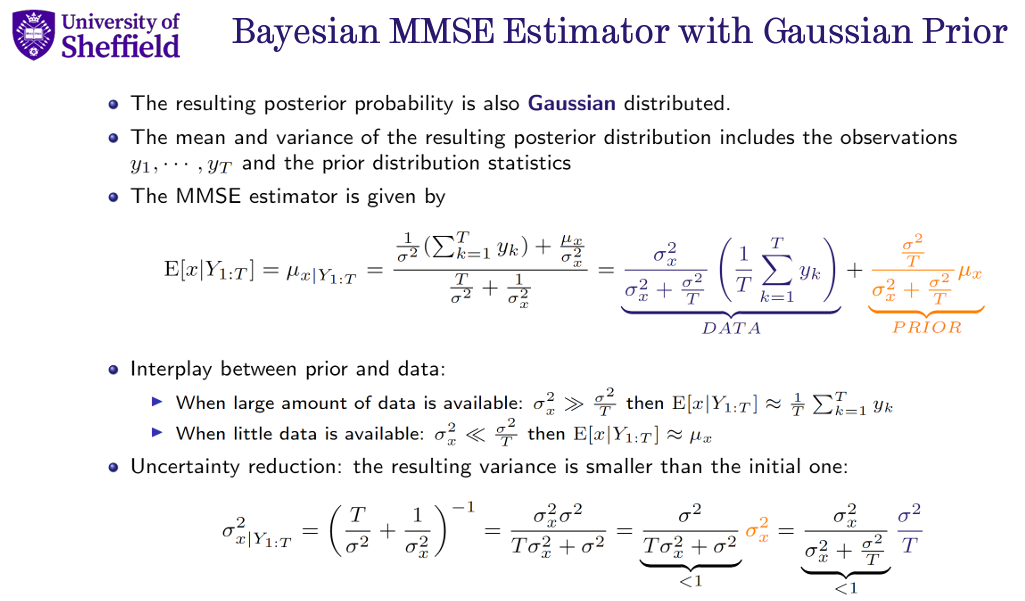

function MMSE_ = MMSE(data, sigma2, xmin, xmax)
% function to calculate the MMSE
    T = size(data, 1);   
    
    % Reused term stored in var a
    a = 2*pi*sigma2/T;
    
    f1 = @(x) (x/sqrt(a)).*exp((-1/a)*(x-(1/T)*sum(data)).^2);
    f2 = @(x) (1/sqrt(a)).*exp((-1/a)*(x-(1/T)*sum(data)).^2);
    
    MMSE_ = integral(f1, xmin, xmax) / integral(f2, xmin, xmax);

end
